# Find Arc Path Function

FINDARCPATH: Finds the circular arc between the pose_begin and the goal_xy point. Returns the velocity V, rotational velocity omega, and time for a trajectory along that arc.

[V,OMEGA,TIME] = FINDARCPATH(POSE_BEGIN,GOAL_XY,MAXWHEELSPEED) returns the maximum forward and angular velocity commands as well as the time needed to drive a differential-drive robot along the arc between a start pose and goal point

INPUTS 

- pose_begin - initial robot pose [x y th] 

- goal_xy - goal point [x y] in global frame`    

- maxWheelSpeed - maximum wheel rotational velocity (rad/s)

OUTPUTS 

- V - scaled forward velocity command (m/s) 

- omega - scaled angular velocity command (rad/s) 

- time - the amount of time needed to complete the trajectory (s)

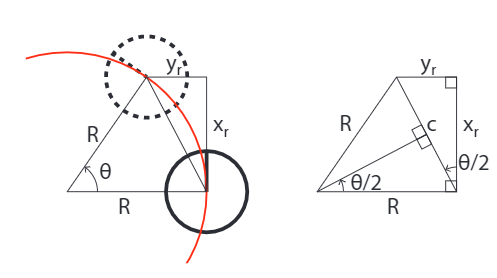

The figure above shows the trigonometry needed to find the radius $R$ and the angle $\theta$ that defines the arc connecting the starting pose (solid) to the goal position (dashed). The chord length squared $c^2$ is given by


$$c^2 = x_r^2 + y_r^2$$


The two triangles with $\theta/2$ have the relations


$$sin(\frac{\theta}{2}) = \frac{y_r}{c} = \frac{c}{2R}$$


so $c^2 = 2Ry_r$ as well.

Therefore, putting that equation with the first gives us an equation for $R$


$$R = \frac{x_r^2 + y_r^2}{2y_r}$$


 Remember $R=\frac{V}{\omega}$

so we're free to choose any $V$ and $\omega$ whose ratio is equal to $R$, so we'll choose the largest values possible that do not surpass the wheel speed limits.

Also, from the diagram we see that 


$$\theta = 2tan^{-1}(y_r/x_r)$$


and we can calculate the time needed to complete the arc by $t = \theta/\omega$.

Use the equations above to finish the function.

function[V,omega,time] = findArcPath(pose_begin,goal_xy,maxWheelSpeed)

Use your transform_points to get the goal coordinates ($x_g$ and $y_g$) into the robot frame ($x_r$ and $y_r$)

goal_xy_robot = transform_points(pose_begin,goal_xy);

We first should check if $y_r$ is non-zero (as otherwise $R$ would be undefined).

if abs(goal_xy_robot(2)) > 10e-5 % y is non-zero

Use the equation above to calculate the radius R

**Complete the code below.**

    R = (goal_xy_robot(1).^2 + goal_xy_robot(2).^2)/(2*goal_xy_robot(2));

We can set a very large magnitude for V, calculated omega, and then scale using the limitCommands function.

    if goal_xy_robot(1) >= 0 
        V = 1000; % Set V positive if goal in front of robot 
    else
        V = -1000; % Set V negative if goal behind robot
    end

Calculate omega from V and R, then scale the commands using limitCommands

**Complete the code below.**

    omega = V/R; 
    [V,omega, scaleFactor] = limitCommands(V,omega,maxWheelSpeed); 

Calculate theta and time using the equations above

**Complete the code below.**

    theta = 2*atan(goal_xy_robot(2)/goal_xy_robot(1)); 
    time = theta/omega; 

This next section is the case where $y_r$ is zero and $x_r$ is non-zero, where the goal is directly in front or behind the robot. Therefore $\omega$ is 0. Set V positive or negative depending on goal location like what was done above. Time needs to be calculated from $t = x_r / V$

**Complete the code below.**

elseif abs(goal_xy_robot(1)) > 10e-5 
    if goal_xy_robot(1) >0 
        V = 1000; 
    else V = -1000; 
    end
    omega = 0;
    % scale the commands using your limitCommands function
    [V,omega] = limitCommands(V,omega,maxWheelSpeed);
    % Calculate trajectory time using goal_xy_robot(1) and V
    time = abs(goal_xy_robot(1)/V); % Calculate trajectory time
    

Finally, the last case is when the goal is at the current pose, and the robot doesn't need to move at all.

**Complete the code below.**

else
    omega = 0; 
    V = 0; 
    time = 0; 
end

end

[](matlab:open('./MAE101_E5.mlx'))